tic;
clc; close all; clear all;
format long
X1=0;
X2=2;

Y1=X2+0.01;
Y2=30+0.01;

n=(X2-X1)*100+1;
m=(Y2-Y1)*100+1;

hx=(X2-X1)/(n-1);
hy=(Y2-Y1)/(m-1);
x=(X1:hx:X2)';
y=(Y1:hy:Y2)';

f1=@(x) sin(pi*x); %%% Model Two: f1=@(x) x.*exp(-x);
F1=f1(x);
for i=1:m
    G1(i,1)=trapz(x,1./(y(i)-x).*F1);
end

f2=@(x) exp(x); %%% Model Two: f2=@(x) x-x;
F2=f2(x);
for i=1:m
    G2(i,1)=trapz(x,1./(y(i)-x).*F2);
end
B1=1; B2=2;
XD=1.01;
b1=XD*B1;b2=XD*B2;%%%%%%%%%%%误差参数的大小
f_exact=B1*F1+B2*F2;
f_delta=b1*F1+b2*F2;

g_exact=B1*G1+B2*G2;
g_delta=b1*G1+b2*G2;

MM=f_delta(1); NN=f_delta(length(x));
V_exact=(MM*(x-X2))/(X1-X2)+(NN*(x-X1))/(X2-X1);
for i=1:m
    G3(i,1)=trapz(x,1./(y(i)-x).*V_exact);
end
U_exact=f_exact-V_exact;
G_exact=g_exact-G3;
G_delta=g_delta-G3;

A=zeros(n,n);
Aphi=zeros(m,n);
for j=2:n-1
    Aphi(:,j)=1/hx*((y-x(j-1)).*log(y-x(j-1))+(x(j-1)-x(j))+(y-x(j+1)).*log(y-x(j+1))-2*(y-x(j)).*log(y-x(j))-(x(j)-x(j+1)));
end
Aphi(:,1)=log(y-x(1))+1/hx*((y-x(2)).*log(y-x(2))-(y-x(1)).*log(y-x(1))-(x(1)-x(2)));
Aphi(:,n)=-log(y-x(n))+1/hx*(-(y-x(n)).*log(y-x(n))+(y-x(n-1)).*log(y-x(n-1))+(x(n-1)-x(n)));

for i=1:n
    for j=1:n
        A(i,j)=trapz(y,Aphi(:,i).*Aphi(:,j));
    end
    ba(i,1)=trapz(y,Aphi(:,i).*G_delta);
end

M=zeros(n,n);
M(1,1)=4;
M(1,2)=2;
for i=2:n-1
    M(i,i)=8;
    M(i,i-1)=2;
    M(i,i+1)=2;
end
M(n,n)=4;
M(n,n-1)=2;
M=hx/12*M;

M1=zeros(n,n);
M1(1,1)=1;
M1(1,2)=-1;
for i=2:n-1
    M1(i,i)=2;
    M1(i,i-1)=-1;
    M1(i,i+1)=-1;
end
M1(n,n)=1;
M1(n,n-1)=-1;
M1=(1/hx)*M1;
H1=M+M1;

A(:,1)=[];A(:,n-1)=[];A(1,:)=[];A(n-1,:)=[];
ba(1)=[];ba(n-1)=[];
H1(:,1)=[];H1(:,n-1)=[];H1(1,:)=[];H1(n-1,:)=[];

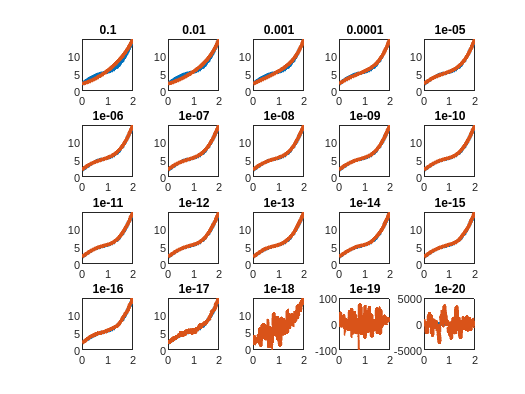

ite=20;
for k=1:ite
    alpha(k)=10^(-k);
    ua(:,k)=inv(A+alpha(k)*H1)*ba;
    Ua(:,k)=[0;ua(:,k);0];
    fa(:,k)=Ua(:,k)+V_exact;
    res(k)=sqrt(trapz(y,(Aphi*fa(:,k)-g_delta).^2));
    err(k)=sqrt(trapz(x,(fa(:,k)-f_exact).^2));

    L(k)=sqrt(trapz(x,fa(:,k).^2))*res(k);%%%%%%%%%%%%L曲线法的选取标准

    LH(k)=sqrt(trapz(x,fa(:,k).^2+(gradient(fa(:,k))).^2))*res(k);

    figure(1)
    subplot(4,5,k);
    plot(x,f_exact,x,fa(:,k),'LineWidth',3);
    title({alpha(k)})
end

kl=find(L==min(abs(L)));

klh=find(LH==min(abs(LH)));

I1=eye(length(y));
I2=eye(length(x));
for i=1:20
    VV=I1-Aphi*inv(Aphi'*Aphi+alpha(i)*I2)*Aphi';
    V1=norm(VV*g_delta)^2;
    V2=trace(VV)^2;
    V(i,1)=V1/V2;
end

[Vm,Vi]=min(V);

for i=1:20
    Rho(i,1)=norm(alpha(i)*(Aphi'*Aphi+alpha(i)*I2)\fa(:,i));
end

[Rm,Ri]=min(Rho);

{'L-curve+L^2','L-curve+H^1','GCV','拟最优';...
    kl,klh,Vi,Ri}

ans = 2x4 cell 数组
    {'L-curve+L^2'}    {'L-curve+H^1'}    {'GCV'}    {'拟最优'}
    {[         17]}    {[         17]}    {[ 10]}    {[    1]}


toc;

历时 5.850693 秒。
